# Data Processing using MATLAB

#### First clear all the variables in the workspace

clear all
clc

## Generating a Sine Wave: A$\sin$($\Omega \;$t)

A = 10;            %Amplitude
Omega = 62.8;        %Frequency(rad/s)
f = Omega/(2*pi);                    %Frequency(Hz)
Fs = 41* f   %Sampling Frequency

Fs = 409.7921

dt = 1/Fs;                           %Time Step
Time = 0:dt:1                      %Time Vector

Time =          0    0.0024    0.0049    0.0073    0.0098    0.0122    0.0146    0.0171    0.0195    0.0220    0.0244    0.0268    0.0293    0.0317    0.0342    0.0366    0.0390    0.0415    0.0439    0.0464    0.0488    0.0512    0.0537    0.0561    0.0586    0.0610    0.0634    0.0659    0.0683    0.0708    0.0732    0.0756    0.0781    0.0805    0.0830    0.0854    0.0878    0.0903    0.0927    0.0952    0.0976    0.1001    0.1025    0.1049    0.1074    0.1098    0.1123    0.1147    0.1171    0.1196


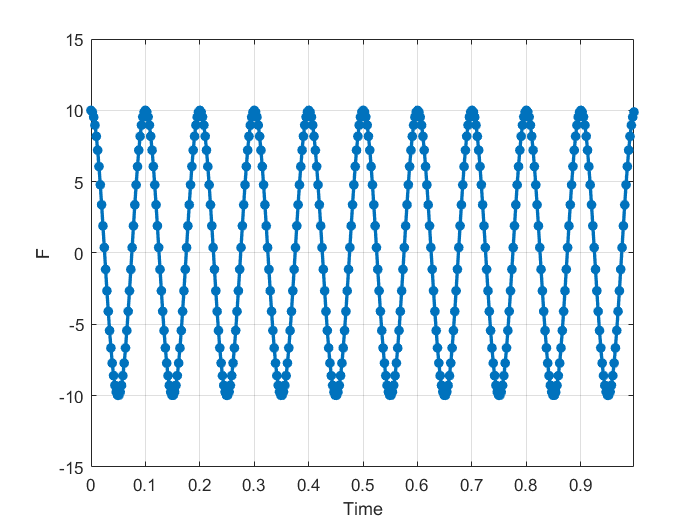


F = A*cos(Omega*Time);%+A/2*sin(2.5*Omega*Time);               %Function

plot(Time,F,'-','Marker','.','MarkerSize',20,'LineWidth',2)
axis([0 Time(end) -1.5*A 1.5*A])
xlabel('Time')
ylabel('F')
grid on

## Windowing

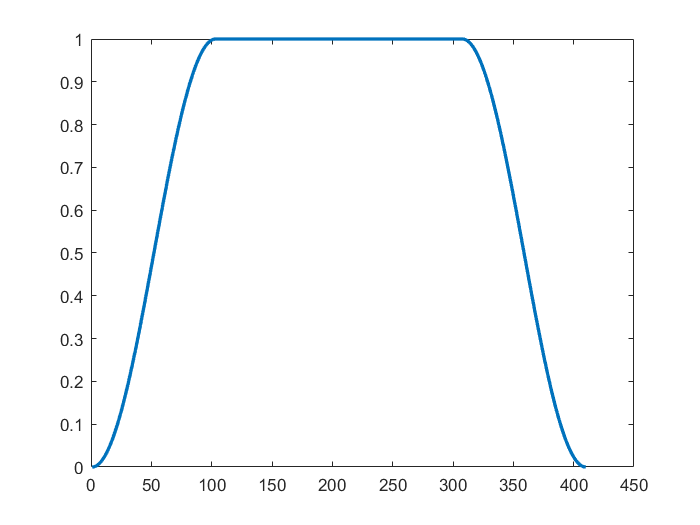

L=length(F);
window = "Tukey";

if window=="No"
    w = ones(L,1);
elseif window=='Hann'
    w = hann(L);
elseif window=='Hamming'
    w = hamming(L);
elseif window=='Welch'
    j = (0:L-1)';
    w = 1 - (2*j/L - 1).^2;
elseif window=='Tukey'
    w = tukeywin(L,0.5);
end
plot(w,'LineWidth',2)

**Explore other types of Windows: **Uncomment the following line to open an app

% windowDesigner

## FFT

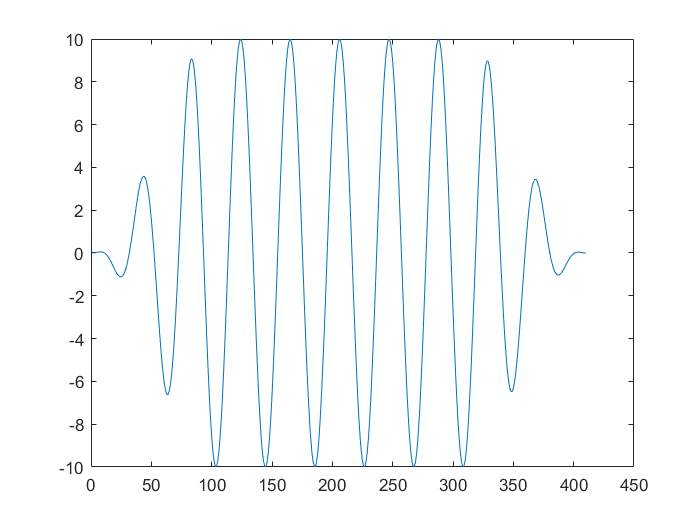

x1=F.*w';
figure
plot(x1)


X1 = fft(x1)/(L/2);
X1 = X1(1:L/2);
mx1 = abs(X1);                      % Take the magnitude of fft of x


f = linspace(0,Fs/2,L/2)

f =          0    1.0044    2.0088    3.0132    4.0176    5.0220    6.0264    7.0307    8.0351    9.0395   10.0439   11.0483   12.0527   13.0571   14.0615   15.0659   16.0703   17.0747   18.0791   19.0835   20.0879   21.0922   22.0966   23.1010   24.1054   25.1098   26.1142   27.1186   28.1230   29.1274   30.1318   31.1362   32.1406   33.1450   34.1493   35.1537   36.1581   37.1625   38.1669   39.1713   40.1757   41.1801   42.1845   43.1889   44.1933   45.1977   46.2021   47.2064   48.2108   49.2152


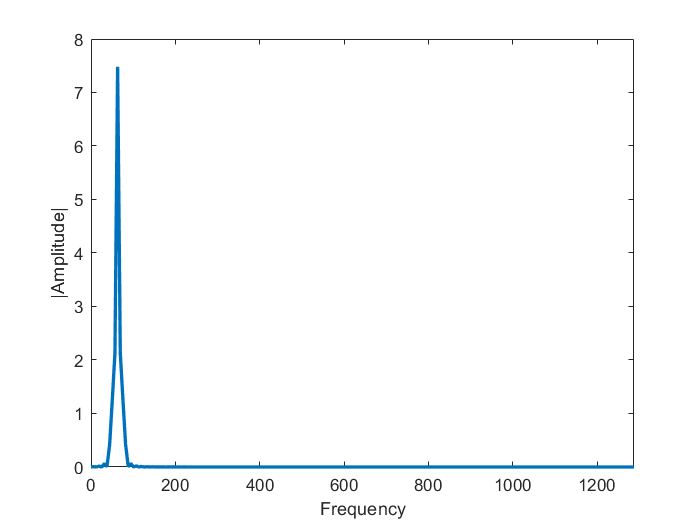


figure                          % Plotting
plot(f*(2*pi),(mx1),'LineWidth',2);               % Convert Hz to radians
xlabel('Frequency')
ylabel('|Amplitude|')
xlim([0 Fs*2*pi/2])

#### Noise

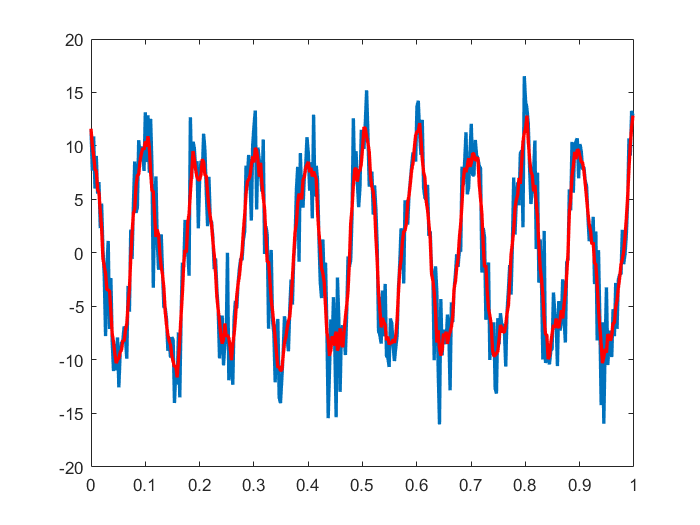

Fnoise = F + 3*randn(size(F));      %adding artificial noise
plot(Time,Fnoise,'LineWidth',2)
Ffiltered = smooth(Fnoise);         %Filtering:moving average (low pass)
hold on
plot(Time,Ffiltered,'r','LineWidth',2)

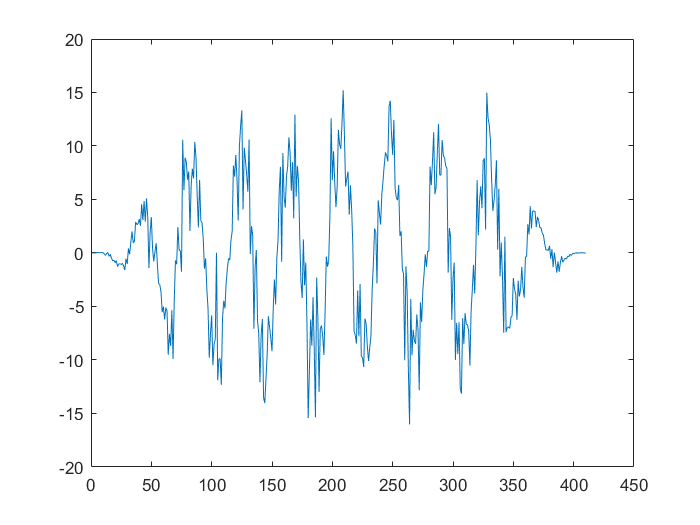

x1=Fnoise.*w';
figure
plot(x1)


X1 = fft(x1)/(L/2);
X1 = X1(1:L/2);
mx1 = abs(X1);                      % Take the magnitude of fft of x


f = linspace(0,Fs/2,L/2)

f =          0    1.0044    2.0088    3.0132    4.0176    5.0220    6.0264    7.0307    8.0351    9.0395   10.0439   11.0483   12.0527   13.0571   14.0615   15.0659   16.0703   17.0747   18.0791   19.0835   20.0879   21.0922   22.0966   23.1010   24.1054   25.1098   26.1142   27.1186   28.1230   29.1274   30.1318   31.1362   32.1406   33.1450   34.1493   35.1537   36.1581   37.1625   38.1669   39.1713   40.1757   41.1801   42.1845   43.1889   44.1933   45.1977   46.2021   47.2064   48.2108   49.2152


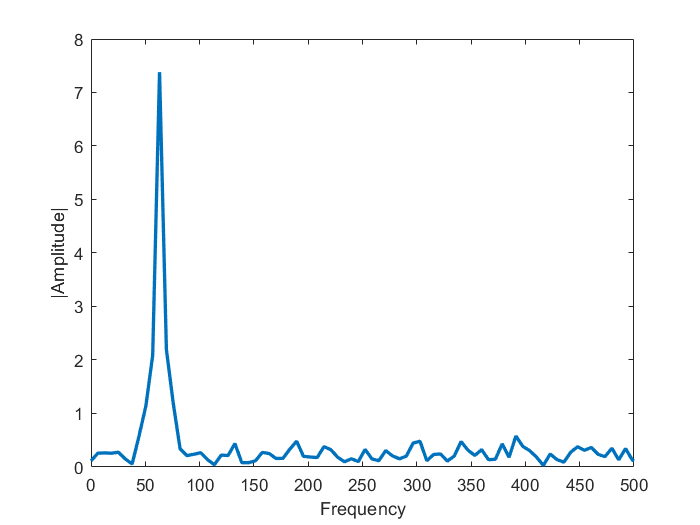


figure                          % Plotting
plot(f*(2*pi),(mx1),'LineWidth',2);               % Convert Hz to radians
xlabel('Frequency')
ylabel('|Amplitude|')
% xlim([0 Fs*2*pi/2])
xlim([0 500])